# **ECON 310: Dynamic Macroeconomics**

### **Spring 2025**

### **Fulbright University Vietnam**

%{

    run_vfi_sgm.mlx
    ---------------
    This code solves the stochastic growth model using value function iteration.

%}

## Model: Stochastic Growth Model.

## The Model.

The optimization problem is

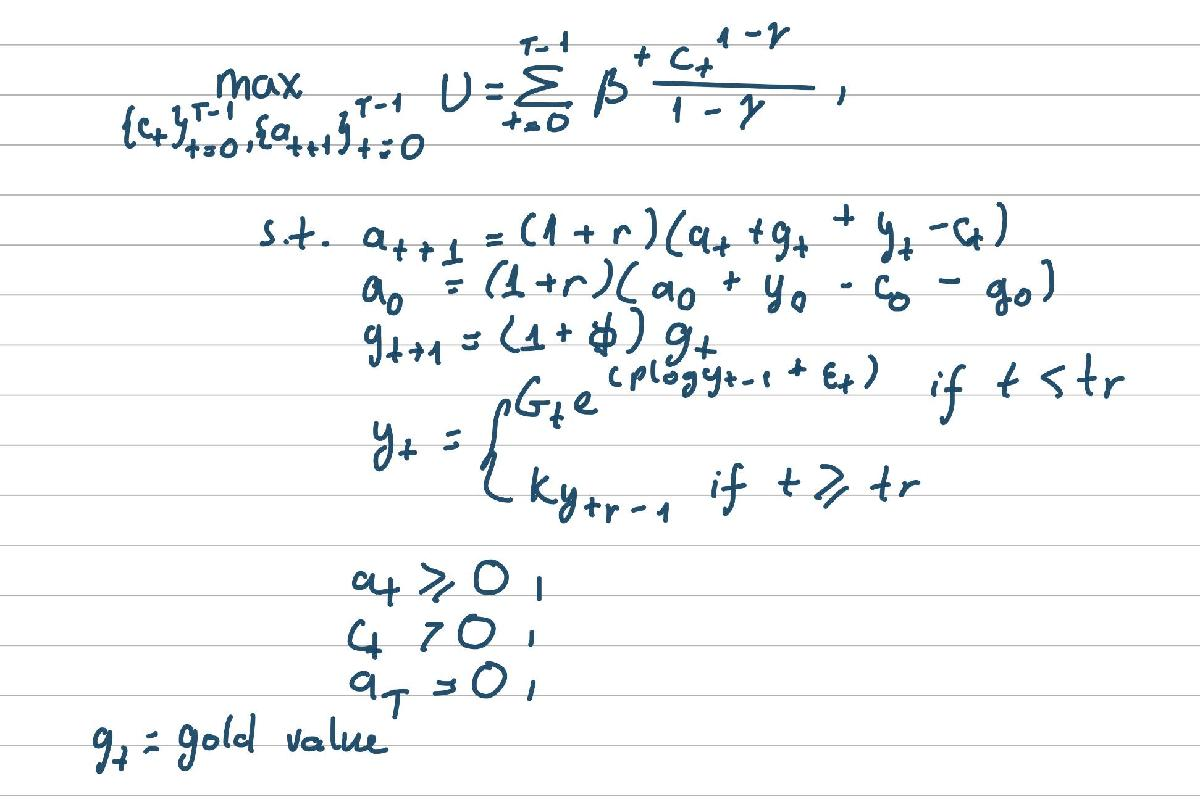

## Recursive Formulation.

The recursive formulation is


$$U_t(a_t) = \underset{c_t, a_{t+1}}{\text{max}}\frac{c_t^{1-\sigma}}{1-\sigma} + \beta U_{t+1}(a_{t+1})$$


 
$$\begin{array}{r l} \text{s.t. } a_{t+1} = (1+r)(a_t + y_t - c_t) \text{ ,}\end{array} $$



$$\[
y_t =
\begin{cases} 
\bar{y} & \text{if } t < t_r, \\
\kappa \bar{y} & \text{if } t \geq t_r,
\end{cases}
\]$$



$$a_0 \text{ given , }$$



$$a_T = 0,$$



$$c_t > 0\text{ .}$$


We have:


$$c_t = -\frac {a_t+1}{1 + r} +a_t+ y_t$$


Substituting the constraint gives


$$V_t(W_t) = \underset{c_t, a_{t+1}}{\text{max}}\frac{\left(\frac{-a_{t+1}}{1+r}+a_t + y_t\right)^{1-\sigma}}{1-\sigma} + \beta U_{t+1}(a_{t+1})$$


## Set up directories and paths.

clc
clear
close all

id = getenv('USERNAME'); % Gets your username.

main = strcat('C:\Users\USER\Documents\GitHub\Problem_Set_2_Dynamic_Macroeconomics\Question 1 - with determinant'); % Project Folder.
cd (strcat(main)) % Set project folder as current working directory.

addpath(genpath(main)) % Add all subfolders in current working directory to path. Note: Make sure file names are unique.

fprintf('The directory is %s \n\n',main)

The directory is C:\Users\USER\Documents\GitHub\Problem_Set_2_Dynamic_Macroeconomics\Question 1 - with determinant 



## Set the parameters and generate the state space.

Calls: model.m.

We cannot directly compute the steady state capital as before because of the productivity fluctuations, but we can still build the grid for $k_t$ around the deterministic steady state.

par = qb_model.setup; % Set parameters.

    Age    MeanLogIncome      Gt  
    ___    _____________    ______

    18        8.9179        7464.2
    19        8.7391        6242.5
    20        9.0004          8106
    21         9.753         17206
    22        9.4334         12499
    23        9.2563         10470
    24        9.7931         17909
    25        9.7885         17827
    26        9.4933         13271
    27        9.5687         14310
    28        9.5448         13972
    29         9.803         18087
    30         9.844         18846
    31        9.7424         17025
    32        9.4747         13027
    33        9.5412         13921
    34        9.6011         14780
    35        9.6213         15082
    36        9.6356         15300
    37        9.4921         13254
    38        9.5728         14369
    39        9.5341         13823
    40        9.4813         13112
    41        9.4115  

par = qb_model.gen_grids(par); % Generate the state space.

## Solve the model using Value Function Iteration.

Calls: hj_solve.m, and hj_model.m.

As in the deterministic case, we will solve the model using value function iteration using 


$$V(k_t) = \frac{1}{1-\beta} \frac{\left(A_tk_t^{\alpha}-(1-\delta)k_t\right)^{1-\sigma}}{1-\sigma} \ ,$$


as a guess.

t = cputime;
sol = qb_solve.cs_qb_model_fin(par); % Solve the model using Value Function Iteration.

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


fprintf('\nModel solved in %0.4f seconds.\n',cputime-t)


Model solved in 1.9844 seconds.


## Simulate the model and plot the model functions and time series.

Calls: simulate.m and my_graph.m.

The model functions behave in a similarly to those in the deterministic growth model. The difference now is that because there are different levels of productivity, there will be a separate function for each level. For example, the seven production functions correspond to different levels of $A_t$. The blue line is production at the lowest level of $A_t$ while the red line is production at the highest level. The general pattern is that the higher $A_t$ is, the more resources there are for consumption, saving, and investment.

Because of productivity fluctuations, there is not a deterministic steady state level. Instead, the variables co-move with the productivity shocks. When productivity is low, output, consumption, and investment are low. Similarly, these variables are high when there are high productivity shocks. Utility in each period fluctuates with consumption.

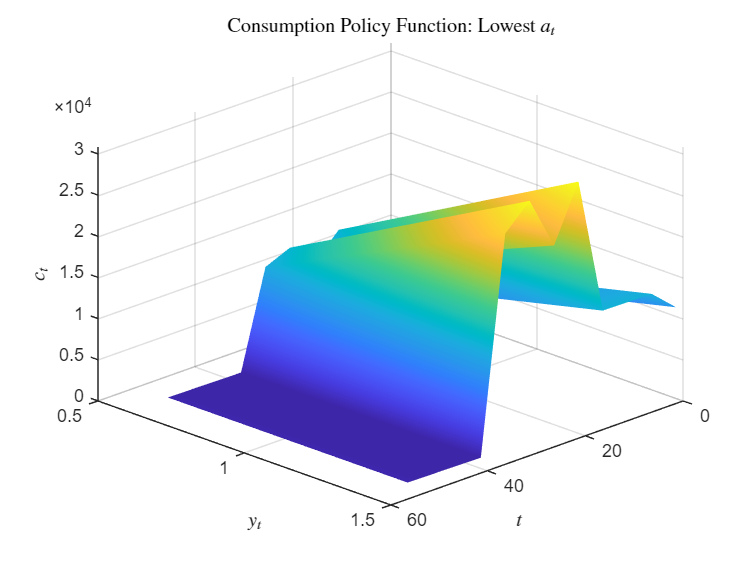

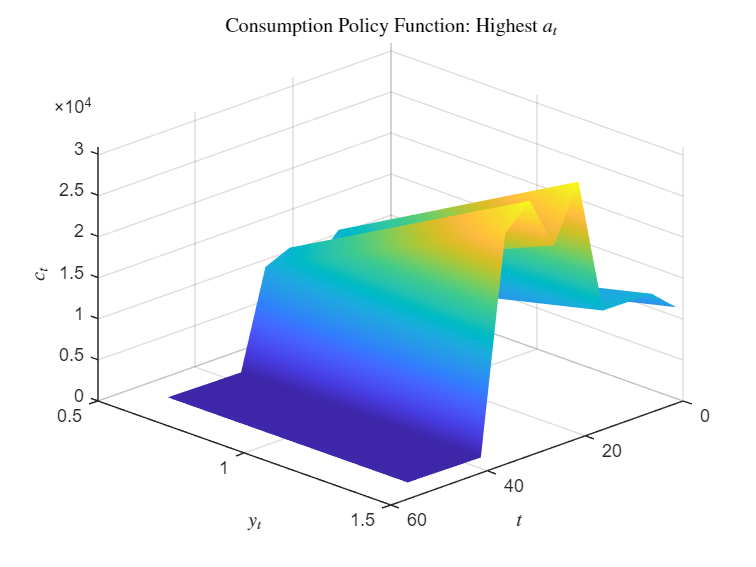

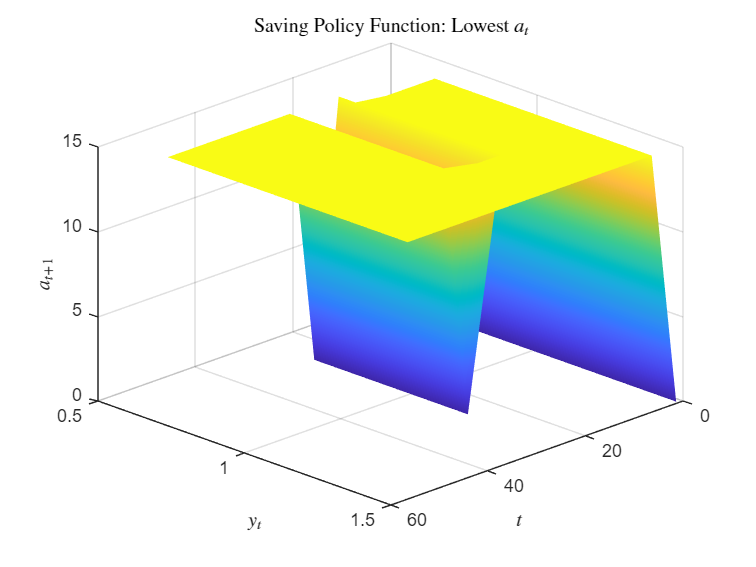

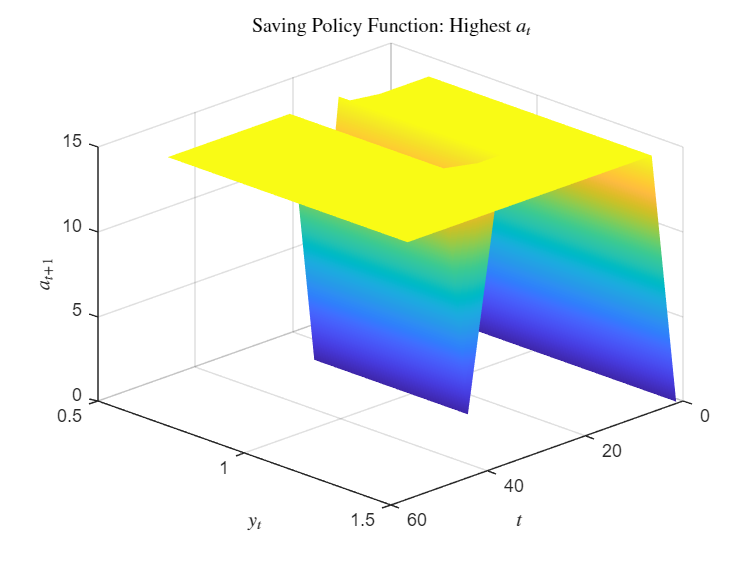

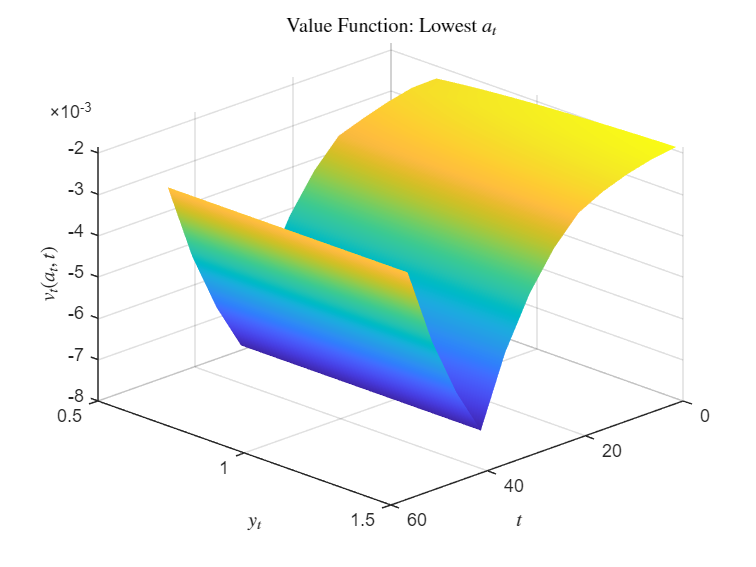

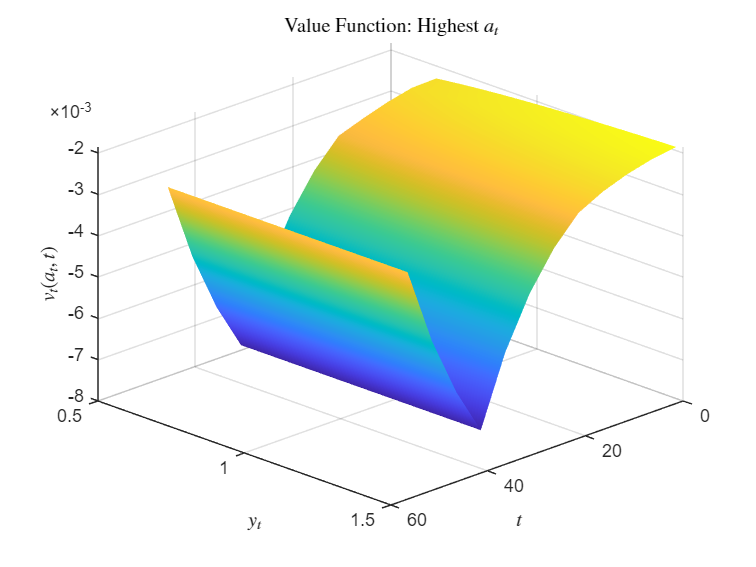

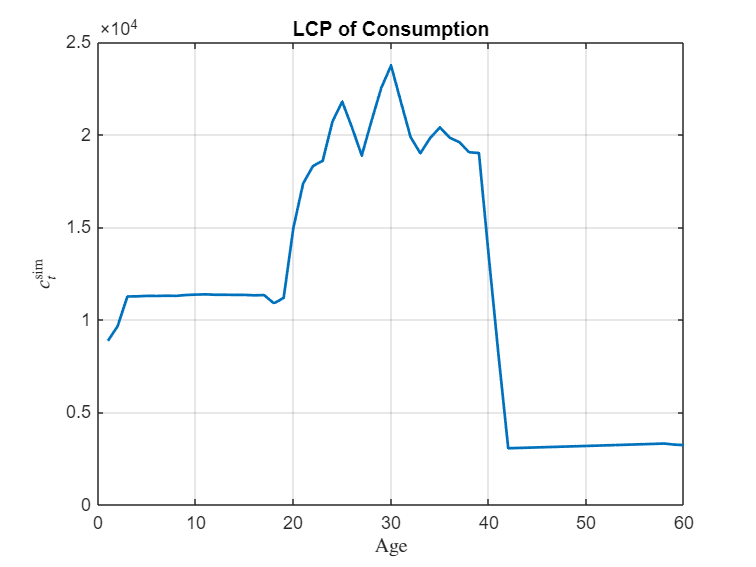

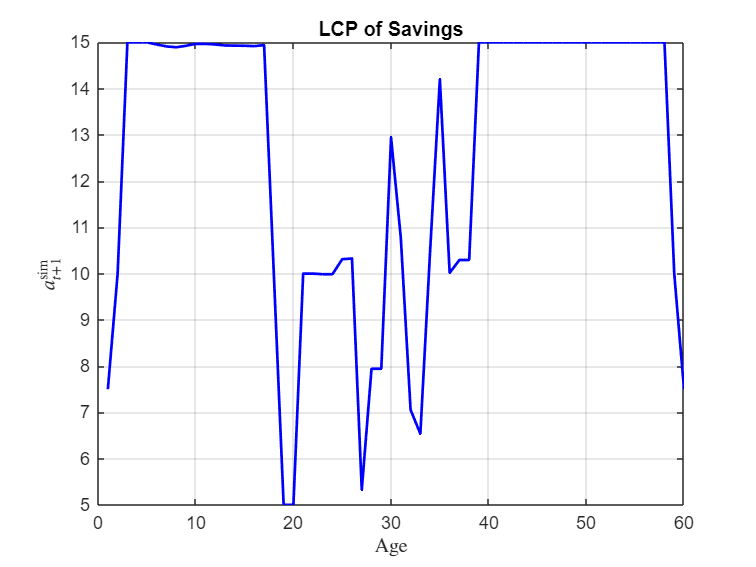

sim = qb_simulate.lc(par, sol); % Simulate the model.
qb_my_graph.plot_policy(par, sol, sim);% Plot the model functions and time series.

beta_list = [0.90, 0.92, 0.94, 0.96];
num_betas = length(beta_list);

lcp_c_all = nan(par.T, num_betas); % Consumption
lcp_a_all = nan(par.T, num_betas); % Assets

age = (1:par.T)'; % Age vector

min_obs = 30;  % Minimum number of observations at each age

for b = 1:num_betas
    % === Set Parameters ===
    par.beta = beta_list(b);
    par.sigma = 2.00;

    % === Solve model ===
    sol = qb_solve.cs_qb_model_fin(par); 

    % === Simulate model ===
    sim = qb_simulate.lc(par, sol);

    % === Compute Smoothed Lifecycle Profiles ===
    lcp_c_all(:, b) = smoothed_profile(sim.csim, sim.tsim, par.T, min_obs);
    lcp_a_all(:, b) = smoothed_profile(sim.Asim, sim.tsim, par.T, min_obs);
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


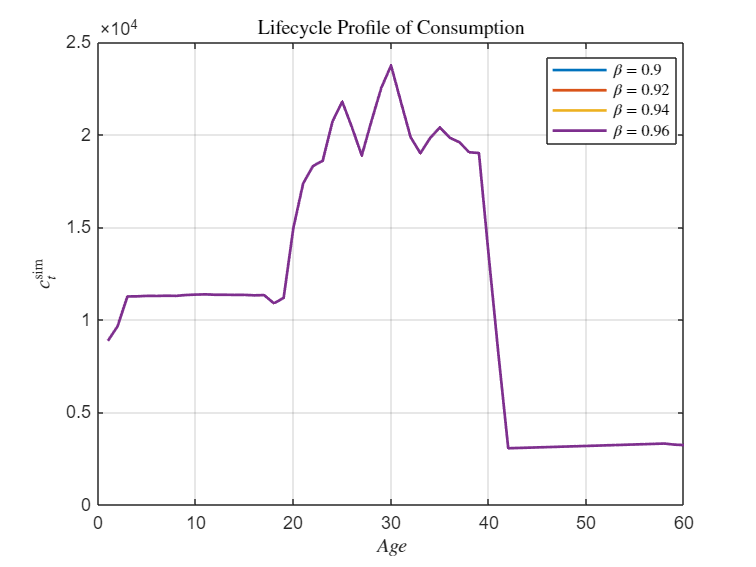


%% Plot Lifecycle Profile of Consumption 
figure;
plot(age, lcp_c_all, 'LineWidth', 1.5)
xlabel('$Age$', 'Interpreter', 'latex')
ylabel('$c^{\mathrm{sim}}_t$', 'Interpreter', 'latex')
legend(arrayfun(@(b) ['$\beta = $' num2str(b)], beta_list, 'UniformOutput', false), ...
    'Interpreter', 'latex', 'Location', 'best')
title('Lifecycle Profile of Consumption', 'Interpreter', 'latex')
grid on

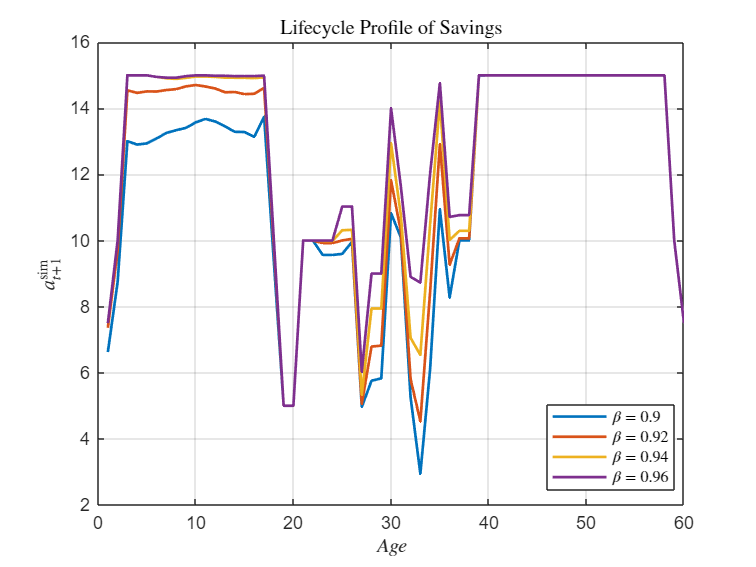


%% Plot Lifecycle Profile of Assets/Savings
figure;
plot(age, lcp_a_all, 'LineWidth', 1.5)
xlabel('$Age$', 'Interpreter', 'latex')
ylabel('$a^{\mathrm{sim}}_{t+1}$', 'Interpreter', 'latex')
legend(arrayfun(@(b) ['$\beta = $' num2str(b)], beta_list, 'UniformOutput', false), ...
    'Interpreter', 'latex', 'Location', 'best')
title('Lifecycle Profile of Savings', 'Interpreter', 'latex')
grid on


%% Local function: smoothed LCP
function profile = smoothed_profile(data, tsim, T, min_obs)
    profile = nan(T,1);
    valid = ~isnan(tsim) & tsim >= 1 & tsim <= T;
    for t = 1:T
        mask = valid & tsim == t & ~isnan(data);
        if sum(mask(:)) >= min_obs
            profile(t) = mean(data(mask), 'omitnan');
        end
    end
    % Apply moving average smoothing
    profile = movmean(profile, 3, 'omitnan');
end


For each combination of γ = {2.00, 3.00, 4.00, 5.00} and β = {0.96}, plot the life cycle pro�les of consumption and wealth in one graph.

sigma_list = [2.00, 3.00, 4.00, 5.00];
num_sigmas = length(sigma_list);

lcp_c_all = nan(par.T, num_sigmas); % Consumption
lcp_a_all = nan(par.T, num_sigmas); % Assets

age = (1:par.T)'; % Age vector
min_obs = 30;     % Minimum observations per age bin

for g = 1:num_sigmas
    % === Set Parameters ===
    par.beta = 0.96;
    par.sigma = sigma_list(g);

    % === Solve model ===
    sol = qb_solve.cs_qb_model_fin(par);

    % === Simulate model ===
    sim = qb_simulate.lc(par, sol);

    % === Compute Smoothed Lifecycle Profiles ===
    lcp_c_all(:, g) = smoothed_profile(sim.csim, sim.tsim, par.T, min_obs);
    lcp_a_all(:, g) = smoothed_profile(sim.Asim, sim.tsim, par.T, min_obs);
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


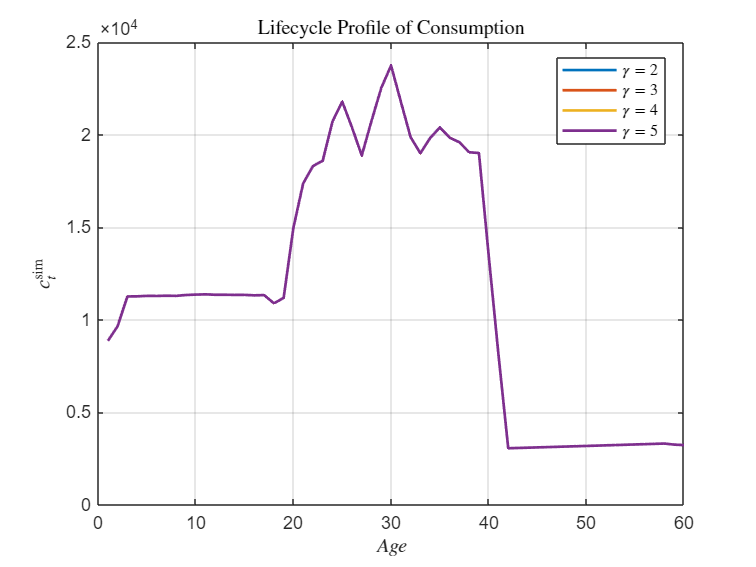


%% Plot Lifecycle Profile of Consumption
figure;
plot(age, lcp_c_all, 'LineWidth', 1.5)
xlabel('$Age$', 'Interpreter', 'latex')
ylabel('$c^{\mathrm{sim}}_t$', 'Interpreter', 'latex')
legend(arrayfun(@(g) ['$\gamma = $' num2str(g)], sigma_list, 'UniformOutput', false), ...
    'Interpreter', 'latex', 'Location', 'best')
title('Lifecycle Profile of Consumption', 'Interpreter', 'latex')
grid on

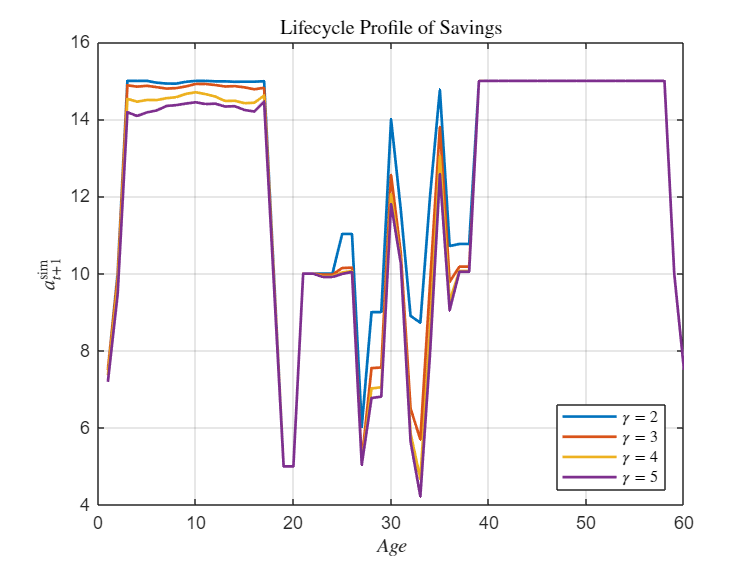


%% Plot Lifecycle Profile of Assets/Savings
figure;
plot(age, lcp_a_all, 'LineWidth', 1.5)
xlabel('$Age$', 'Interpreter', 'latex')
ylabel('$a^{\mathrm{sim}}_{t+1}$', 'Interpreter', 'latex')
legend(arrayfun(@(g) ['$\gamma = $' num2str(g)], sigma_list, 'UniformOutput', false), ...
    'Interpreter', 'latex', 'Location', 'best')
title('Lifecycle Profile of Savings', 'Interpreter', 'latex')
grid on

For each combination of γ = {2.00, 3.00, 4.00, 5.00} and β = {{0.90, 0.92, 0.94, 0.96}, compute average simulated wealth in the simulated economy and plot these in a heat map with γ on the x-axis and β on the y-axis

sigma_list = [2.00, 3.00, 4.00, 5.00];
beta_list = [0.90, 0.92, 0.94, 0.96];
num_sigmas = length(sigma_list);
num_betas = length(beta_list);

avg_wealth_matrix = nan(num_betas, num_sigmas); % Rows: beta, Cols: gamma

for i = 1:num_betas
    for j = 1:num_sigmas
        % Set parameters
        par.beta = beta_list(i);
        par.sigma = sigma_list(j);

        % Solve and simulate
        sol = qb_solve.cs_qb_model_fin(par);
        sim = qb_simulate.lc(par, sol);

        % Compute average simulated wealth (across all agents and time)
        avg_wealth = mean(sim.Asim(:), 'omitnan');
        avg_wealth_matrix(i, j) = avg_wealth;
    end
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.

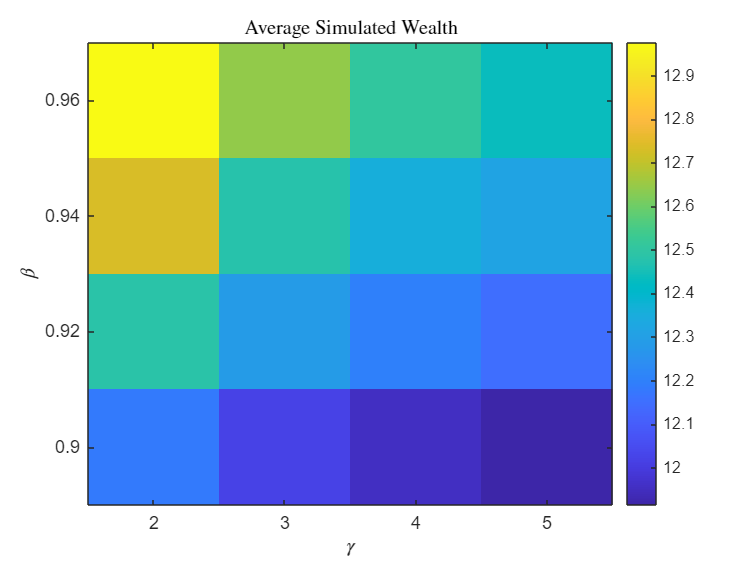


%% Plot Heatmap
figure;
imagesc(sigma_list, beta_list, avg_wealth_matrix);
colormap('parula'); colorbar;

% Labeling
xlabel('$\gamma$', 'Interpreter', 'latex');
ylabel('$\beta$', 'Interpreter', 'latex');
title('Average Simulated Wealth', 'Interpreter', 'latex');

% Tick marks
set(gca, 'XTick', sigma_list);
set(gca, 'YTick', beta_list);

% Display numeric values in each heatmap cell
textStrings = strtrim(cellstr(num2str(avg_wealth_matrix(:), '%.2f')));
[x, y] = meshgrid(1:num_sigmas, 1:num_betas);
text(x(:), y(:), textStrings, ...
     'HorizontalAlignment', 'center', 'Color', 'w', 'FontSize', 10);

% Optional: enhance axes appearance
set(gca, 'YDir', 'normal'); % flip y-axis to make beta increase upward